noise_type_str = ["NO NOISE", "BIT FLIP", "DEPOLARIZING", "DEPHASING", "AMPLITUDE DAMPING"];
noise_types_list = [0, 1, 2, 4];

noise_p=0.001;
lambda=2;
offset=2;
dt=0.005;
nqubits=9;
init_cond=0;

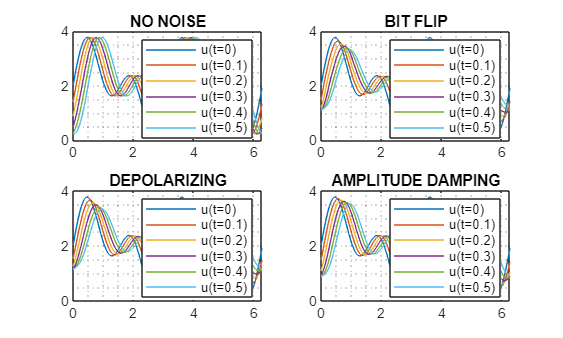

fig_showcase = figure(Position=[0,0,1280,768]);
for i = 1:4
    noise_type = noise_types_list(i);
    name = strcat(noise_type_str(noise_type+1), num2str(noise_p),...
        '_lambda',num2str(lambda),...
        '_offset',num2str(offset),...
        '_dt', num2str(dt),...
        '_nqubits',num2str(nqubits),...
        '_initCond',num2str(init_cond));
    load(strcat('DATA/MAT_',name,'.mat'));
    
    subplot(2,2,i); hold on;
    % Plot 6 lines
    nlines=6;
    step=floor((length(t)-1)/(nlines-1));
    for it = 1:step:length(t)
        plot(x,u(it,:), 'DisplayName',strcat('u(t=',num2str(dt*(it-1)),')'));
    end
    hold off;
    legend(FontSize=8);
    box on;
    grid minor;
    title(noise_type_str(noise_type+1));
end
figname=strcat('p', num2str(noise_p),...
    '_lambda',num2str(lambda),...
    '_offset',num2str(offset),...
    '_dt', num2str(dt),...
    '_nqubits',num2str(nqubits));
savefig(fig_showcase, strcat('FIG/showcase_', figname,'.fig'))
exportgraphics(fig_showcase, strcat('FIG/showcase_', figname,'.pdf'));